clear variables

sysFull = load("Data\SimulateData\sysFull.mat");
sysReduced = load("Data\SimulateData\sysReduced.mat");
sysFull = sysFull.sys;
sysReduced = sysReduced.sysModal;

disTime = 0.02;
sysFullDis = c2d(dss2ss(sysFull),disTime);
sysReducedDis = c2d(dss2ss(sysReduced),disTime);

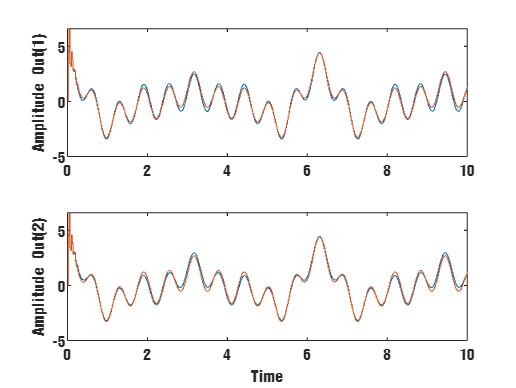

% 系统输出仿真
u = @(t) [cos(10*t) * ones(1, 1);cos(2*t) * ones(1, 1);cos(3*t) * ones(1, 1); cos(4*t) * ones(1, 1)];
figure
opts = struct('InputFcn', u, 'TimeRange', 10);
ml_dt_dss_simulate(sysFullDis,sysReducedDis, opts);

错误使用 DynamicSystem/lsim
无法仿真具有奇异 E 矩阵的模型的状态轨迹。请使用 "isproper" 命令检查模型是否适当，并提取对等的显式表示。